clear all
d1=load("precipitation\PPT_zscore.mat");
d2=load("Soil moisture\SM_zscore.mat");
d3=load("L band VOD\VOD_zscore.mat");
d4=load("SIF data\SIF_zscore.mat");
d5=load("SPI weekly\SPI_1month_08_18.mat");
d6=load("VODCA VOD\VOD_X_zscore.mat");
d7=load("VODCA VOD\VOD_C_zscore.mat");


ppt=d1.Z(:,:,1:132);
sm=d2.Z(:,:,1:132);
vod=d3.Z(:,:,1:132);
sif=d4.Z(:,:,1:132);
spi=d5.SPI(:,:,1:132);
vod_x=d6.Z(:,:,1:132);
vod_c=d7.Z(:,:,1:132);

year=2016;

x1=26;
y1=48;
lat=ppt(x1,1,1);
long=ppt(1,y1,1);

for p=1:132
    if (floor(ppt(1,1,p)/100))==year
        ind_start=p;
        break
    end
end
ind_end=ind_start+11;

mo=1:12;

for k=1:12
    m(k)=month(datetime(1,k,1), 'name');
end

mon=["Feb","Apr","Jun","Aug","Oct","Dec"]';
% mon=["Jan","Mar","May","Jul","Sept","NOV"];

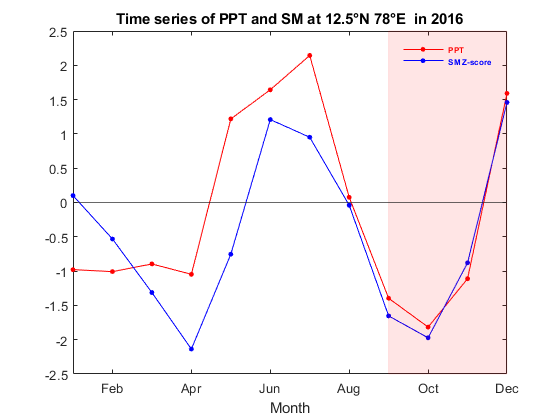

%TS for ppt and sm zscore
for x=x1      %lat values 2:130
    for y=y1     %long values 2:136
        
        p=squeeze(ppt(x,y,ind_start:ind_end));
        s=squeeze(sm(x,y,ind_start:ind_end));
        
        
        f1=figure(1);
        plot(p,"-o",'MarkerSize',3,'MarkerEdgeColor','red','MarkerFaceColor',"red","Color","red");
        xticks([2 4 6 8 10 12]);
        xlim([1 12]);
        %xticklabels(["jan","feb","mar","apr","may","jun","jul","aug","sep","oct","nov","dec"]);
        set(gca,'xticklabel',mon);
        hold on
        plot(s,"-o",'MarkerSize',3,'MarkerEdgeColor','blue','MarkerFaceColor',"blue","Color","blue");
        %         ylabel("PPT (mm)");
        %         plot(p_st_u,"g");
        %         plot(p_st_d,"g");
        j=yline(0);
        j.Annotation.LegendInformation.IconDisplayStyle = 'off';
        lgd=legend("\color{red}\bf PPT","\color{blue}\bf SM Z-score");
        lgd.FontSize=6;
        legend boxoff;
        xlabel("Month");
        title("Time series of PPT and SM"+" at "+num2str(lat)+"°N "+num2str(long)+"°E "+" in "+num2str(year));
        %         j=jbfill((1:12),p_st_u',p_st_d',"g","g",1,0.25);
        %         j.Annotation.LegendInformation.IconDisplayStyle = 'off';
        lim=get(gca,'ylim');
        up=[lim(2),lim(2),lim(2),lim(2)];
        do=[lim(1),lim(1),lim(1),lim(1)];
%         q=jbfill((6:9),up,do,"r","r",1,0.1);
%         q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        q=jbfill((9:12),up,do,"r","r",1,0.1);
        q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        hold off
        
    end
end

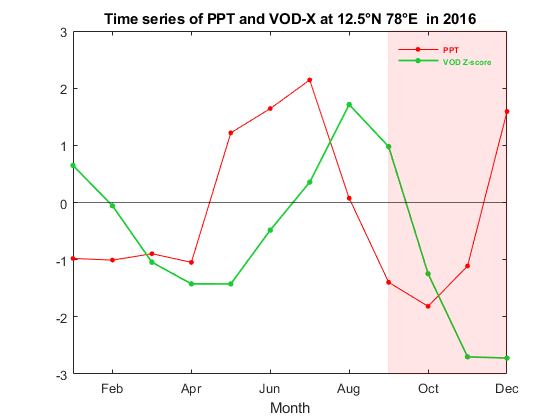


%TS for ppt and vod-X zscore
for x=x1      %lat values 2:130
    for y=y1     %long values 2:136
        
        p=squeeze(ppt(x,y,ind_start:ind_end));
        s=squeeze(vod_x(x,y,ind_start:ind_end));
        
        
        f1=figure(1);
        plot(p,"-o",'MarkerSize',3,'MarkerEdgeColor','red','MarkerFaceColor',"red","Color","red");
        xticks([2 4 6 8 10 12]);
        xlim([1 12]);
        %xticklabels(["jan","feb","mar","apr","may","jun","jul","aug","sep","oct","nov","dec"]);
        set(gca,'xticklabel',mon);
        hold on
        plot(s,"-o",'MarkerSize',3,'MarkerEdgeColor',[0.1 0.8 0.2],'MarkerFaceColor',[0.1 0.8 0.2],"Color",[0.1 0.8 0.2],'linewidth',1.25);
        %         ylabel("PPT (mm)");
        %         plot(p_st_u,"g");
        %         plot(p_st_d,"g");
        j=yline(0);
        j.Annotation.LegendInformation.IconDisplayStyle = 'off';
        lgd=legend("\color{red}\bf PPT","\color[rgb]{0.1 0.8 0.2}\bf VOD Z-score");
        lgd.FontSize=6;
        legend boxoff;
        xlabel("Month");
        title("Time series of PPT and VOD-X"+" at "+num2str(lat)+"°N "+num2str(long)+"°E "+" in "+num2str(year));
        %         j=jbfill((1:12),p_st_u',p_st_d',"g","g",1,0.25);
        %         j.Annotation.LegendInformation.IconDisplayStyle = 'off';
        lim=get(gca,'ylim');
        up=[lim(2),lim(2),lim(2),lim(2)];
        do=[lim(1),lim(1),lim(1),lim(1)];
%         q=jbfill((6:9),up,do,"r","r",1,0.1);
%         q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        q=jbfill((9:12),up,do,"r","r",1,0.1);
        q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        hold off
        
    end
end

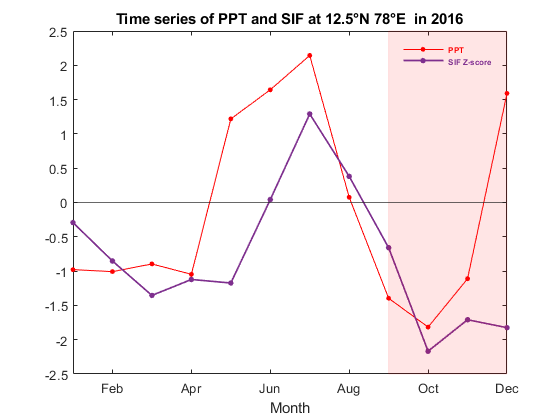

%TS for ppt and sif zscore
for x=x1      %lat values 2:130
    for y=y1     %long values 2:136
        
        p=squeeze(ppt(x,y,ind_start:ind_end));
        s=squeeze(sif(x,y,ind_start:ind_end));
        
        
        f1=figure(1);
        plot(p,"-o",'MarkerSize',3,'MarkerEdgeColor','red','MarkerFaceColor',"red","Color","red");
        xticks([2 4 6 8 10 12]);
        xlim([1 12]);
        %xticklabels(["jan","feb","mar","apr","may","jun","jul","aug","sep","oct","nov","dec"]);
        set(gca,'xticklabel',mon);
        hold on
        plot(s,"-o",'MarkerSize',3,'MarkerEdgeColor',[0.4940 0.1840 0.5560],'MarkerFaceColor',[0.4940 0.1840 0.5560],"Color",[0.4940 0.1840 0.5560],'linewidth',1.25);
        %         ylabel("PPT (mm)");
        %         plot(p_st_u,"g");
        %         plot(p_st_d,"g");
        j=yline(0);
        j.Annotation.LegendInformation.IconDisplayStyle = 'off';
        lgd=legend("\color{red}\bf PPT","\color[rgb]{0.4940 0.1840 0.5560}\bf SIF Z-score");
        lgd.FontSize=6;
        legend boxoff;
        xlabel("Month");
        title("Time series of PPT and SIF"+" at "+num2str(lat)+"°N "+num2str(long)+"°E "+" in "+num2str(year));
        %         j=jbfill((1:12),p_st_u',p_st_d',"g","g",1,0.25);
        %         j.Annotation.LegendInformation.IconDisplayStyle = 'off';
        lim=get(gca,'ylim');
        up=[lim(2),lim(2),lim(2),lim(2)];
        do=[lim(1),lim(1),lim(1),lim(1)];
%         q=jbfill((6:9),up,do,"r","r",1,0.1);
%         q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        q=jbfill((9:12),up,do,"r","r",1,0.1);
        q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        hold off
        
    end
end

function[fillhandle,msg]=jbfill(xpoints,upper,lower,color,edge,add,transparency)
%USAGE: [fillhandle,msg]=jbfill(xpoints,upper,lower,color,edge,add,transparency)
%This function will fill a region with a color between the two vectors provided
%using the Matlab fill command.
%
%fillhandle is the returned handle to the filled region in the plot.
%xpoints= The horizontal data points (ie frequencies). Note length(Upper)
%         must equal Length(lower)and must equal length(xpoints)!
%upper = the upper curve values (data can be less than lower)
%lower = the lower curve values (data can be more than upper)
%color = the color of the filled area
%edge  = the color around the edge of the filled area
%add   = a flag to add to the current plot or make a new one.
%transparency is a value ranging from 1 for opaque to 0 for invisible for
%the filled color only.
%
%John A. Bockstege November 2006;
%Example:
%     a=rand(1,20);%Vector of random data
%     b=a+2*rand(1,20);%2nd vector of data points;
%     x=1:20;%horizontal vector
%     [ph,msg]=jbfill(x,a,b,rand(1,3),rand(1,3),0,rand(1,1))
%     grid on
%     legend('Datr')
if nargin<7;transparency=.5;end %default is to have a transparency of .5
if nargin<6;add=1;end     %default is to add to current plot
if nargin<5;edge='k';end  %dfault edge color is black
if nargin<4;color='b';end %default color is blue

if length(upper)==length(lower) && length(lower)==length(xpoints)
    msg='';
    filled=[upper,fliplr(lower)];
    xpoints=[xpoints,fliplr(xpoints)];
    if add
        hold on
    end
    fillhandle=fill(xpoints,filled,color);%plot the data
    set(fillhandle,'EdgeColor',edge,'FaceAlpha',transparency,'EdgeAlpha',transparency);%set edge color
    if add
        hold off
    end
else
    msg='Error: Must use the same number of points in each vector';
end
end
